# 线性规划求解资产组合问题

本节通过线性规划, 为资产组合的有效前沿作进一步探讨.

首先解决例题中的问题, 设定收益率和风险.

clear
rtn = [.1; .3];
sigma = [.02 0; 0 .04];

以及线性规划的特殊条件.


$$\begin{array}{l}
w_1 +w_2 =1\\
w_1 \le 0\ldotp 2\\
w_2 \ge 0\ldotp 3
\end{array}$$


对于Groups, LowerGroup, UpperGroup的每一行, 都有


$$\mathrm{LowerGroup}\ldotp *\mathrm{Group}\le \mathrm{可行域}\le \mathrm{UpperGroup}\;\ldotp *\mathrm{Group}$$


Groups = [1 0; 0 1];
LowerGroup = [0; 0.3];
UpperGroup = [0.2; 1];

构建限制条件矩阵, 该矩阵是线性规划的标准形式.

ConSet = portcons('default', 2, ...  % 有2种资产
    'grouplims', Groups, LowerGroup, UpperGroup)  % 资产小分组

ConSet =     1.0000    1.0000    1.0000
   -1.0000   -1.0000   -1.0000
   -1.0000         0         0
         0   -1.0000         0
   -1.0000         0         0
         0   -1.0000   -0.3000
    1.0000         0    0.2000
         0    1.0000    1.0000


构建投资组合模型.

p = Portfolio;
p = setAssetMoments(p, rtn, sigma);

加入线性规划限制. A是线性规划不等式左边的系数, b是不等式右边的值.

A = ConSet(:, 1:end-1);
b = ConSet(:, end);
p = setInequality(p, A, b);

计算风险边界上n个点的单个资产权重.

n = 100;
PortWts = estimateFrontier(p, n)

PortWts =     0.2000    0.1980    0.1960    0.1939    0.1919    0.1899    0.1879    0.1859    0.1838    0.1818    0.1798    0.1778    0.1758    0.1737    0.1717    0.1697    0.1677    0.1657    0.1636    0.1616    0.1596    0.1576    0.1556    0.1535    0.1515    0.1495    0.1475    0.1455    0.1434    0.1414    0.1394    0.1374    0.1354    0.1333    0.1313    0.1293    0.1273    0.1253    0.1232    0.1212    0.1192    0.1172    0.1152    0.1131    0.1111    0.1091    0.1071    0.1051    0.1030    0.1010
    0.8000    0.8020    0.8040    0.8061    0.8081    0.8101    0.8121    0.8141    0.8162    0.8182    0.8202    0.8222    0.8242    0.8263    0.8283    0.8303    0.8323    0.8343    0.8364    0.8384    0.8404    0.8424    0.8444    0.8465    0.8485    0.8505    0.8525    0.8545    0.8566    0.8586    0.8606    0.8626    0.8646    0.8667    0.8687    0.8707    0.8727    0.8747    0.8768    0.8788    0.8808    0.8828    0.8848    0.8869    0.8889    0.8909    0.8929    0.8949    0.897

计算风险边界上n个点对应的风险和回报.

[PortRisk, PortReturn] = estimatePortMoments(p, PortWts);
disp([PortRisk, PortReturn, [1:n]']);

    0.1625    0.2600    1.0000
    0.1628    0.2604    2.0000
    0.1632    0.2608    3.0000
    0.1635    0.2612    4.0000
    0.1639    0.2616    5.0000
    0.1642    0.2620    6.0000
    0.1646    0.2624    7.0000
    0.1649    0.2628    8.0000
    0.1653    0.2632    9.0000
    0.1656    0.2636   10.0000
    0.1660    0.2640   11.0000
    0.1664    0.2644   12.0000
    0.1667    0.2648   13.0000
    0.1671    0.2653   14.0000
    0.1674    0.2657   15.0000
    0.1678    0.2661   16.0000
    0.1681    0.2665   17.0000
    0.1685    0.2669   18.0000
    0.1689    0.2673   19.0000
    0.1692    0.2677   20.0000
    0.1696    0.2681   21.0000
    0.1700    0.2685   22.0000
    0.1703    0.2689   23.0000
    0.1707    0.2693   24.0000
    0.1710    0.2697   25.0000
    0.1714    0.2701   26.0000
    0.1718    0.2705   27.0000
    0.1721    0.2709   28.0000
    0.1725    0.2713   29.0000
    0.1729    0.2717   30.0000
    0.1732    0.2721   31.0000
    0.1736    0.2725   32.0000
    0.17

绘制有效前沿.

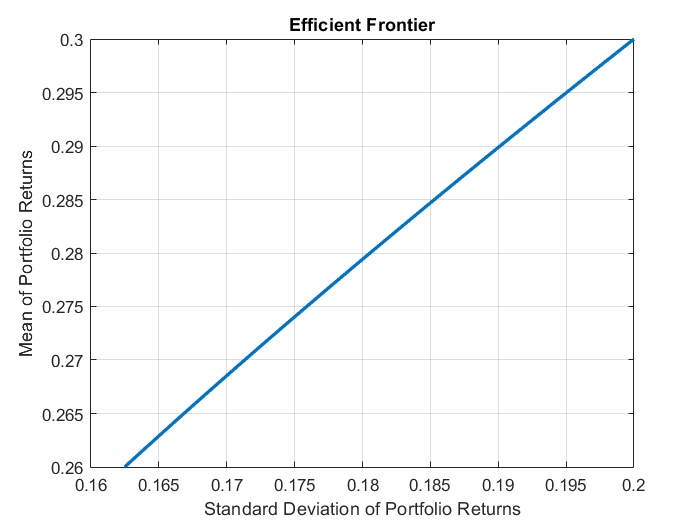

plotFrontier(p, n)

考虑复杂的情景, 上一节中50个股票的有效前沿.

读入上一节处理过的数据.

clear
load data

提出假设条件:

(1) 任意20个股票相加不能超过70%.

(2) 单个股票不超过资产组合的5%.

对于假设1. 还记得Monte-Carlo模拟法吗? 在统计学中, 没有绝对的"任意", 枚举完所有的20个股票组合要$C_{50}^{20}$个条件, 不可能实现.

simu = 100;  % 模拟次数, 次数很大时消耗算力很大.
mat1 = zeros(simu, 50);
for i=1:simu
    idx = randsample(50, 20);
    mat1(i, idx) = ones(1, 20);  % 系数矩阵
end
ug1 = 0.7 * ones(simu, 1);  % 资产上限

对于假设2. 对角矩阵即可限制.

mat2 = eye(50);  % 系数矩阵
ug2 = .05 * ones(50, 1);  % 资产上限

拼接条件.

Group = [mat1; mat2];
LowerGroup = zeros(simu+50, 1);
UpperGroup = [ug1; ug2];
ConSet = portcons('default', 50, 'grouplims', Group, LowerGroup, UpperGroup);

资产组合.

p = Portfolio;
p = setAssetMoments(p, data.rtn, data.sigma);
A = ConSet(:, 1:end-1);
b = ConSet(:, end);
p = setInequality(p, A, b);

绘制有效前沿.

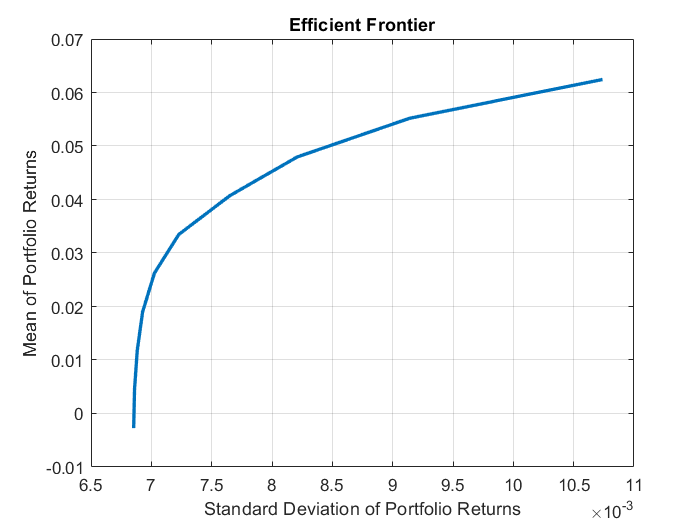

n = 10;  % n较大时消耗算力很大
plotFrontier(p, n)